load("sampleEEGdata.mat")

## Computing ERP at each electrode

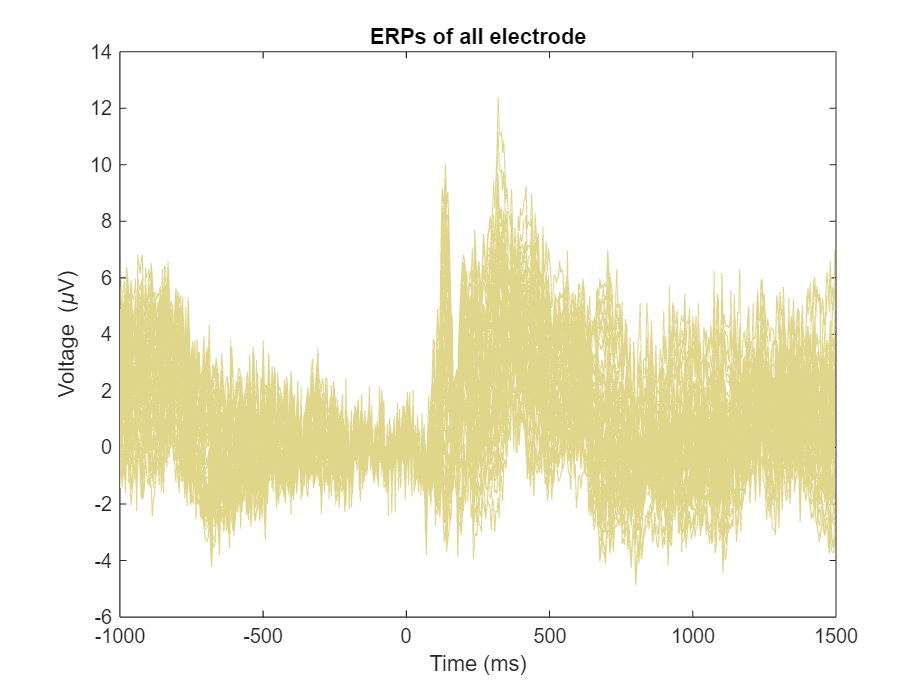

figure;
erpTable = squeeze(mean(EEG.data,3));
plot(EEG.times, erpTable, Color="#E0D68A")
title('ERPs of all electrode')
ylabel('Voltage (\muV)')
xlabel('Time (ms)')
hold off

## Find the peak time of ERP of each between 100ms to 400ms

figure;
peak_times = zeros([1,64]);
t_100 = find(EEG.times >= 100,1)

t_100 = 283

t_400 = find(EEG.times <= 400, 1, "last")

t_400 = 359

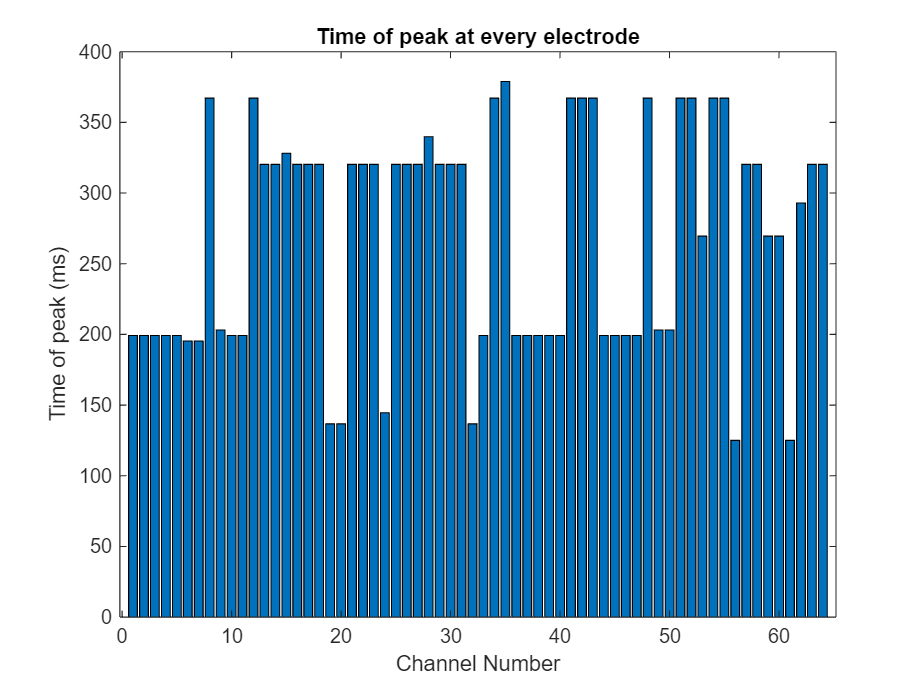


for i = 1:EEG.nbchan
  peak_times(i) = EEG.times(t_100 - 1 + find(erpTable(i,t_100:t_400) == max(erpTable(i,t_100:t_400)),1));

end

bar(peak_times)
title("Time of peak at every electrode")
xlabel("Channel Number")
ylabel("Time of peak (ms)")
hold off

## Plot the peak times in a topographical map

figure;
subplot(1,2,1)
[~,~,~,~,~,xi,yi,pltchans] = topoplot(zeros(64,1),EEG.chanlocs,'electrodes','off','plotrad',.53);

mn_peak_times = min(peak_times)

mn_peak_times = 125

c = peak_times - mn_peak_times;
mx_peak_times = max(c)

mx_peak_times = 253.9062

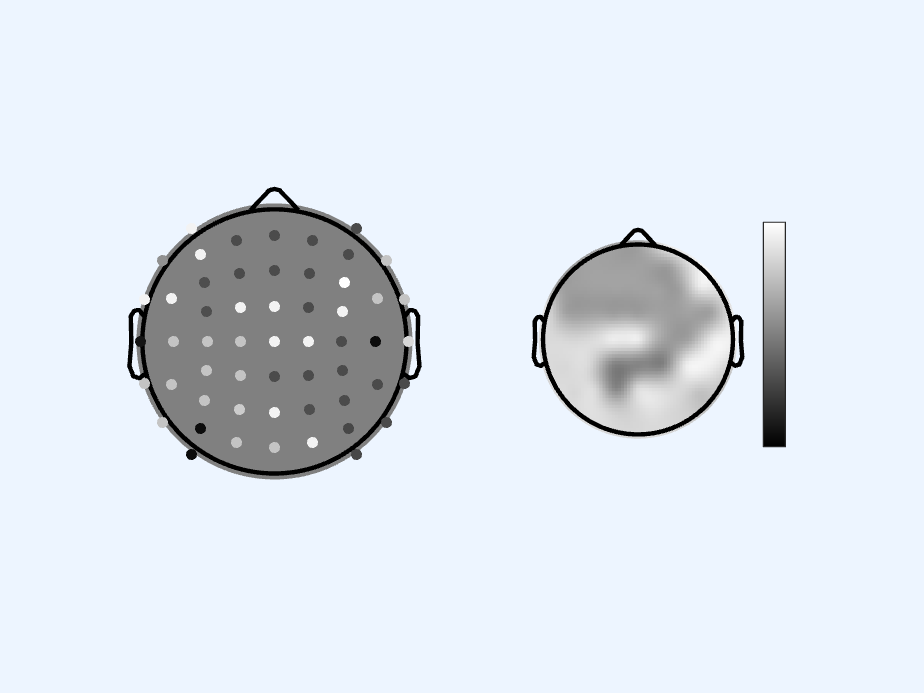

c = c./mx_peak_times;
c = repmat(c,3,1);
hold on

for i = 1:length(xi)
    plot3(xi(i), yi(i), .1,'o', 'MarkerFaceColor',c(:,i),'MarkerSize',5, MarkerEdgeColor='none')
    hold on
end
hold off


subplot(1,2,2)
topoplot(c(2,:),EEG.chanlocs,'plotrad',.53,'electrodes','off','numcontour',0);
colormap gray
colorbar('Ticks',mn_peak_times:50:mx_peak_times + mn_peak_times, 'TickLabels',[mn_peak_times:50:mx_peak_times + mn_peak_times])

figure;
subplot(1,2,1)
[~,~,~,~,~,xi,yi,pltchans] = topoplot(zeros(64,1),EEG.chanlocs,'electrodes','off','plotrad',.53);
mn_peak_times = min(peak_times);
mx_peak_times = max(peak_times);

% Normalize values between 0 and 1 for color mapping
normalized_peaks = (peak_times - mn_peak_times) / (mx_peak_times - mn_peak_times);
c = repmat(normalized_peaks,3,1)

c =     0.2923    0.2923    0.2923    0.2923    0.2923    0.2769    0.2769    0.9538    0.3077    0.2923    0.2923    0.9538    0.7692    0.7692    0.8000    0.7692    0.7692    0.7692    0.0462    0.0462    0.7692    0.7692    0.7692    0.0769    0.7692    0.7692    0.7692    0.8462    0.7692    0.7692    0.7692    0.0462    0.2923    0.9538    1.0000    0.2923    0.2923    0.2923    0.2923    0.2923    0.9538    0.9538    0.9538    0.2923    0.2923    0.2923    0.2923    0.9538    0.3077    0.3077
    0.2923    0.2923    0.2923    0.2923    0.2923    0.2769    0.2769    0.9538    0.3077    0.2923    0.2923    0.9538    0.7692    0.7692    0.8000    0.7692    0.7692    0.7692    0.0462    0.0462    0.7692    0.7692    0.7692    0.0769    0.7692    0.7692    0.7692    0.8462    0.7692    0.7692    0.7692    0.0462    0.2923    0.9538    1.0000    0.2923    0.2923    0.2923    0.2923    0.2923    0.9538    0.9538    0.9538    0.2923    0.2923    0.2923    0.2923    0.9538    0.3077    0

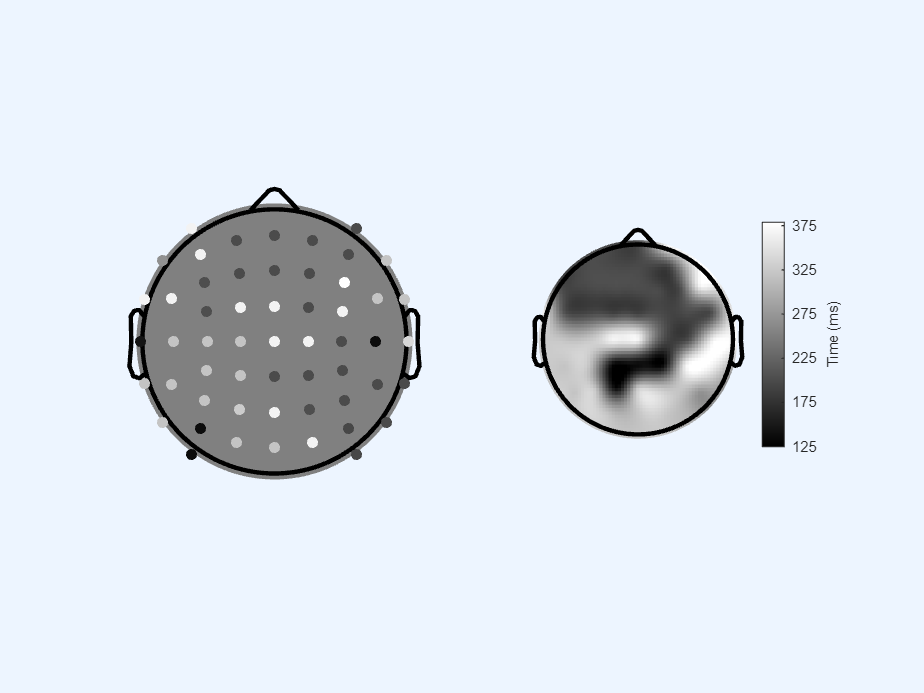


hold on
for i = 1:length(xi)
    plot3(xi(i), yi(i), .1,'o', 'MarkerFaceColor',c(:,i),'MarkerSize',5, 'MarkerEdgeColor','none')
    hold on
end
hold off

subplot(1,2,2)
topoplot(peak_times,EEG.chanlocs,'plotrad',.53,'electrodes','off','numcontour',0);
colormap gray

% Create colorbar with actual peak time values
h = colorbar;
caxis([mn_peak_times mx_peak_times])  % Set color axis limits explicitly
step_size = 50;  % Define step size in milliseconds
tick_values = mn_peak_times:step_size:mx_peak_times;
set(h, 'YTick', tick_values)
ylabel(h, 'Time (ms)')